# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

filename="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.getStateNames);
State=convertStringsToChars(States(1));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.getSampleNames);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Perform Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);

Process Exergy Cost

Key        P*(kW)     Pe*(kW)     Pr*(kW)      F*(kW)      R*(kW)
——————————————————————————————————————————————————————————————————
BLR       115.033     100.000      15.033     100.000      15.033
TRB       104.894      90.440      14.454     104.535       0.359
IHE         3.688       2.906       0.783       3.359       0.330
PMP         5.100       4.220       0.880       4.894       0.206
CND        15.928      13.780       2.148      15.928       0.000


Process Unit Exergy Cost

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.5514      1.3486      0.2027      1.0000      0.2027      1.3486
TRB        2.0000      1.7244      0.2756      1.5918      0.0068      1.2521
IHE        2.3905      1.8832      0.5072      1.5918      0.2137      1.3675
PMP        2.4366      2.0161      0.4206      2.0000      0.0984      1.1691
CND        1.5918  

#### Show the default thermoeconomic analysis graph

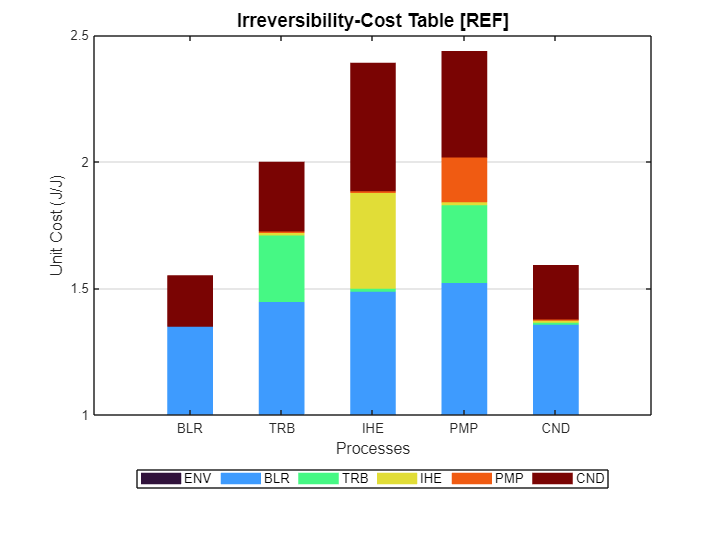

ShowGraph(res);